## Beyond Nearly-Even Chords:

## Graph-Based Modulation Exercises for Guitar

*21st Century Guitar Conference*

*10:00am EDT, Thursday, March 17, 2022*

Lauren C. Ruth, Ph.D. (she/her)

Assistant Professor

Department of Mathematics and Computer Sciences

Mercy College (Dobbs Ferry, NY, USA)

`www.mercy.edu/directory/lauren-ruth`

Put M, m, hm, hM into matrix. Find 4-note chords, printing intervals, key, mode, scale, and notes.

M=[2 2 1 2 2 2 1];  %Major
m=[2 1 2 2 2 2 1];   %melodic minor
hm=[2 1 2 2 1 3 1];  %harmonic minor
hM=[2 2 1 2 1 3 1];  %harmonic Major

scaleMatrix=[M; m; hm; hM];
scaleMatrix2=cat(2,scaleMatrix,scaleMatrix);

n=0;
chordsModesKeysScalesRoots=[];
for K=0:11                                  % goes through keys
    for s=1:4                               % goes through scales
        for i=1:7                           % goes through modes
            for j=(i+1):i+6
               for k=(j+1):i+6
                  for l=(k+1):i+6
                       n=n+1;
                       int1=sum(scaleMatrix2(s,i:j-1));         %------------
                       int2=sum(scaleMatrix2(s,j:k-1));         % four intervals
                       int3=sum(scaleMatrix2(s,k:l-1));         %
                       int4=sum(scaleMatrix2(s,l:i+6));         %------------
                       note1=mod(K+sum(scaleMatrix2(s,1:i))-scaleMatrix2(s,i),12);  %------------
                       note2=mod(note1+int1,12);                                    % four notes
                       note3=mod(note2+int2,12);                                    %
                       note4=mod(note3+int3,12);                                    %------------
                       chordsModesKeysScalesRoots(end+1,:)=[int1, 
                        int2, 
                        int3, 
                        int4,
                        i,                       % mode  
                        K,                       % key   
                        s,                       % scale 
                        note1, 
                        note2, 
                        note3, 
                        note4];
                    end
               end
           end
        end
    end    
end

Group together chord families.

sameChordNotes=[];
m=0;
for i=1:size(chordsModesKeysScalesRoots,1) % i runs down rows of chordsModesKeysScalesRoots
    if ismember(i,sameChordNotes)==0 %  checks if row number has already been assigned to a family in sameChordNotes
        n=0; % resets sameChordNotes column to 0
        m=m+1; % increments sameChordNotes row for next entries
        for j=i:size(chordsModesKeysScalesRoots,1) % checks all chords (there can't be any BEFORE i in same family, because then i would have been entered in sameChordNotes)
            for k=0:3
                if isequal(chordsModesKeysScalesRoots(j,[8:11]),circshift(chordsModesKeysScalesRoots(i,[8:11]),k))==1 % checks if the notes are exactly the same
                    n=n+1;
                    sameChordNotes(m,n)=j;
                end
            end        
        end   
    end
end

Create adjacency matrix for graph, then build graph.

adjMat=zeros(393);
for i=1:size(sameChordNotes, 1) % goes through 393 families
    noteGroup=chordsModesKeysScalesRoots(sameChordNotes(i,1),8:11); % gets original chord to modify
    for j=1:4 % goes through chord note by note
        if mod(noteGroup(j)+1,12)~=noteGroup(1+mod((j-1)+1,4)) % makes sure you don't create illegal comparison chord
            cfNoteGroup=noteGroup;
            cfNoteGroup(j)=mod(noteGroup(j)+1,12); % creates modified chord to compare
            for k=1:size(sameChordNotes, 1) % goes through families 
                if k~=i && adjMat(i,k)~=1
                    inSameChordNotes=chordsModesKeysScalesRoots(sameChordNotes(k,1),8:11); % member of family to compare
                    for l=0:3
                        if isequal(inSameChordNotes, circshift(cfNoteGroup,l))==1 
                            adjMat(i,k)=1; % enters 1 in adjacency matrix
                            adjMat(k,i)=1; % (adjacency matrix is symmetric)
                        end
                    end
                end
            end
        end
    end
end

G=graph(adjMat);

Do random walk on graph to generate first page.  

x=randi(393);
seq=[x];
for i=1:79 %for 80-chord sequence 
    N=neighbors(G,x);
    next=randi(size(N,1));
    x=N(next);
    seq(end+1)=x;
end

Plot graph and highlight traversed nodes.  

compseq=[ 321   367    45   367   322    16    45    62   295   354 ...   
    59   354   356   217   389    93   242   368   389   368   ...
    242    68   295   354   295   305   295    94   295    68   ...
    242    68    51    26     3   174   211   174   384    76    ...
    57    70   275   264    74    71   74    85   282   264   ...
    111   264   282    85    34    85   325   136   233   188   ...
    345   167   157   154   359   261   250     9    44    15   ...
    320   138   320    15   320   138   117   138   307   138 ]

compseq =    321   367    45   367   322    16    45    62   295   354    59   354   356   217   389    93   242   368   389   368   242    68   295   354   295   305   295    94   295    68   242    68    51    26     3   174   211   174   384    76    57    70   275   264    74    71    74    85   282   264


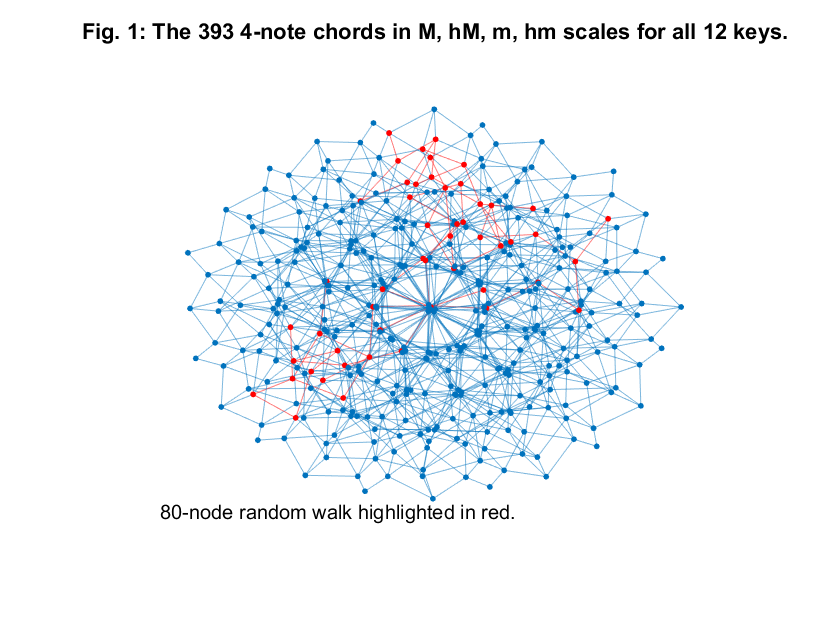


h=plot(G);
box off;
set(gca,'XColor','none','YColor','none');
highlight(h,[compseq],'NodeColor','r', 'EdgeColor','r');
title('Fig. 1: The 393 4-note chords in M, hM, m, hm scales for all 12 keys.')
text(-6.4,-6,'80-node random walk highlighted in red.')

Set the rules for generating the LaTeX file.

keyMaster=["\nicefrac{B$^\sharp$}{C}", "\nicefrac{C$^\sharp$}{D$^\flat$}", "D", "\nicefrac{D$^\sharp$}{E$^\flat$}", "\nicefrac{E}{F$^\flat$}", "\nicefrac{E$^\sharp$}{F}", "\nicefrac{F$^\sharp$}{G$^\flat$}", "G", "\nicefrac{G$^\sharp$}{A$^\flat$}", "A", "\nicefrac{A$^\sharp$}{B$^\flat$}", "\nicefrac{B}{C$^\flat$}"]; % all flat

%skip every other to make room for tab
coordMapPg=[  {'(1,10.2)'}  {'(5,10.2)'}  ...
    {'(1,8)'}  {'(5,8)'}  ...
    {'(1,5.8)'} {'(5,5.8)'}  ...
    {'(1,3.6)'}  {'(5,3.6)'}  ...
    {'(1,1.4)'}  {'(5,1.4)'} ]; %10 total
coordKeyPg=[  {'(1,9.2)'}  {'(5,9.2)'} ...
    {'(1,7)'}  {'(5,7)'} ...
    {'(1,4.8)'}  {'(5,4.8)'}  ...
    {'(1,2.6)'}  {'(5,2.6)'} ...
    {'(1,.4)'} {'(5,.4)'} ]; %10 total

scaleMaster=["M","m","hm","hM"];

formatSpec0= '\\multido{\\ia=0+30}{12}{\\uput*{1}[\\ia]%s{\\pscircle[linecolor=black,fillstyle=solid,fillcolor=white]{0.1} }} \r\n';
formatSpec1='\\uput*{1.2}[%d]%s{\\psframebox*{%s}} \r\n \\uput*{1}[%d]%s{\\pscircle[linecolor=black,fillstyle=solid,fillcolor=black]{0.1}} \r\n';
formatSpec2='\\rput[c]%s{\\psframebox*[linewidth=.5pt]{\\parbox[c]{5cm}{\\centering %s }}} \r\n \r\n'; 

Then print everything

for pg=1:8
new_filespec = sprintf('GuitarConfComp_%d.tex', pg);
fid = fopen( new_filespec, 'w' );
%print preamble and opening material
fprintf( fid , '\r\n%s\r\n\r\n','\documentclass{article} \usepackage[paperheight=11in,paperwidth=8.5in,margin=0pt]{geometry} \usepackage{pstricks} \usepackage{multido} \usepackage{nicefrac} \begin{document} \psset{algebraic,xunit=1in,yunit=1in} \begin{pspicture}(0,0)(8.5,11) \psset{framesep=1.5pt}');
    for i=1:10 %need to create new coordMap         
        fprintf( fid, formatSpec0, coordMapPg{i}); %draws blank diagram --- need this to skip every other, to make room for tabs
        for j=8:11 %fills in chord 
            noteNumber=chordsModesKeysScalesRoots(sameChordNotes(seq(i+(pg-1)*10),1),j);
            fprintf( fid, formatSpec1, 30*mod(-noteNumber+3,12), coordMapPg{i}, keyMaster( noteNumber+1 ), 30*mod(-noteNumber+3,12), coordMapPg{i});
           %keyMaster( noteNumber ) writes name of note
           %30*mod(-noteNumber+3,12) degree where note appears
        end  
           %now get all the keys...
           [~,ind]=min(sameChordNotes(seq(i+(pg-1)*10),:)); % finds first zero entry in row of chord family
            if ind==1 % this is what happens if there are no zeros; the first entry is always the minimum
             famMat=chordsModesKeysScalesRoots(sameChordNotes(seq(i+(pg-1)*10),1:size(sameChordNotes,2)),:); % size(sameChordNotes,2) = 32
            else 
              famMat=chordsModesKeysScalesRoots(sameChordNotes(seq(i+(pg-1)*10),1:ind-1),:); % makes matrix with all family info
            end
              [~,startNote]=min(famMat(:,8));
%    famNotes=keyMaster(famMat(startNote,8:11)+1); don't need famNotes
 %   here, already took care of them above
           possibleKeys=strings(0);
            for j=1:4:size(famMat,1)
        % the same combination appears 4 times in a row; this^ skips 3 of them
           if j==1 || ( j>1 && keyMaster(famMat(j,6)+1)==keyMaster(famMat(j-4,6)+1) )
            possibleKeys(end+1)=strcat(" ", keyMaster(famMat(j,6)+1), "$_{", scaleMaster(famMat(j,7)), "}$ ");
             else 
            possibleKeys(end+1)=strcat("\\", keyMaster(famMat(j,6)+1), "$_{", scaleMaster(famMat(j,7)), "}$ "); %new line for new keys
          end
       end
    toPrint=strcat(join(possibleKeys)); %possibly get rid of strcat
    %now write all possible keys 
    fprintf( fid, formatSpec2, coordKeyPg{i}, toPrint);
    end   
%now make the tabs
fprintf( fid , '\r\n%s\r\n\r\n','\multido{\nq=2.20+4.00,\nqq=3.20+4.00}{2}{	\multido{\ns=10.80+-2.20,\nss=9.20+-2.20}{5}{ \multido{\na=\ns+-.32}{6}{\pscustom[linewidth=1.134pt]{\newpath\moveto(\nq,\na)\lineto(\nqq,\na)}} \multido{\nb=\nq+.20}{6}{\pscustom[linewidth=.751pt]{\newpath\moveto(\nb,\ns)\lineto(\nb,\nss)}}  }  } \end{pspicture}  \end{document}')

fclose(fid);
end

%if you want to get all of them on the same file:
%fprintf( fid, '\r\n%s\r\n\r\n',' \end{pspicture} \pagebreak \begin{pspicture}(0,0)(8.5,11) ');
